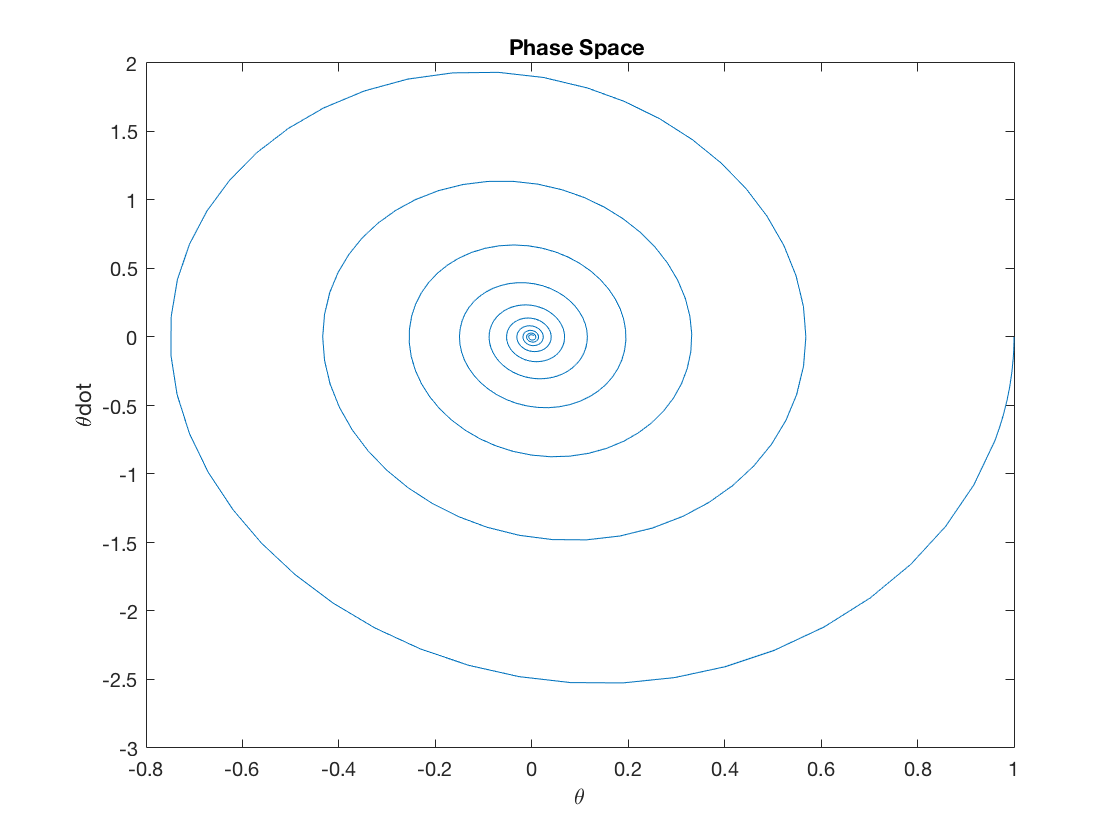

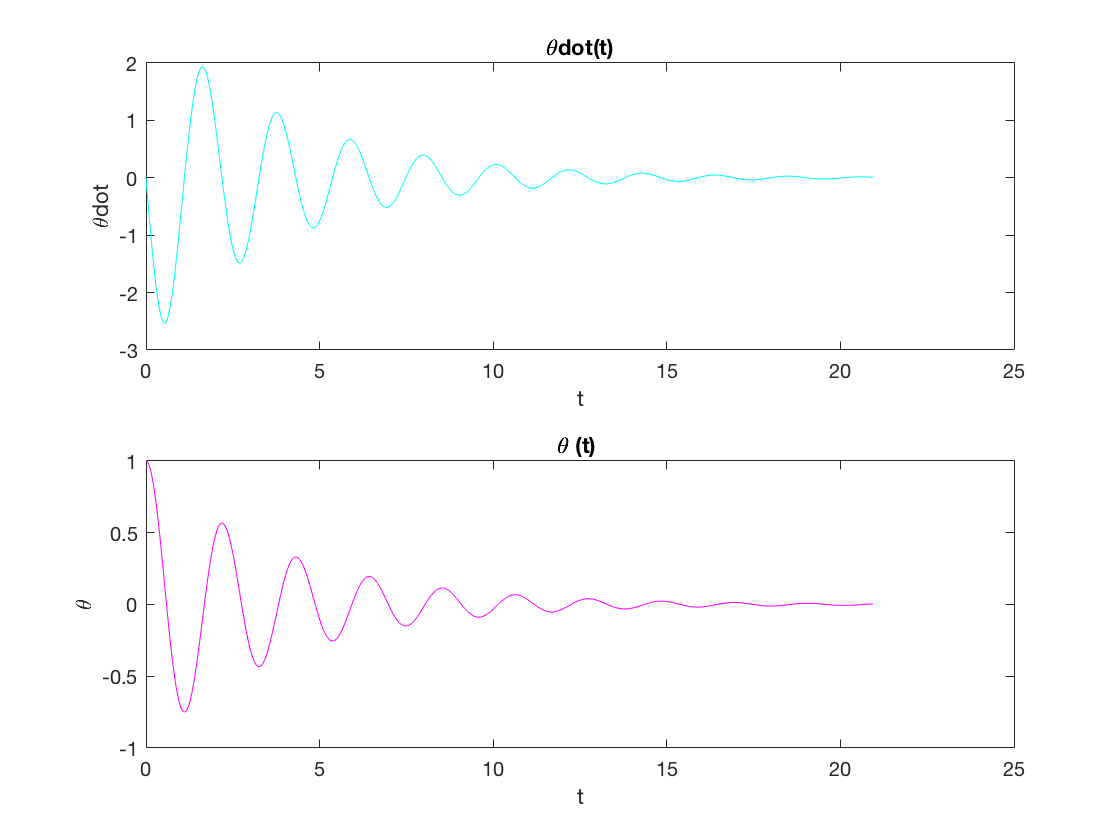

%Damped_pendulummodified
% a)plot time dependence of position and velocity
%omega0 = 3, theta0= 1.0, theta0dot =0 and gamma =0.5
T=Damped_pendulummodified(1.09, 1, 0, 1, 0.5);

% b) compare the period and angular frequency 
%to the undamped case


%T_2 = Damped_pendulummodified(1.09, 1, 0, 1, 0.5);
T_2 = Damped_pendulummodified(1.09, 1, 0, 0,0.5);
fprintf('damped:   T = %f , omega = %f ', T, 6.28./T);

damped:   T = 2.094395 , omega = 2.998479 

fprintf('undamped: T = %f , omega = %f ', T_2, 6.28./T_2);

undamped: T = 2.094395 , omega = 2.998479 


%angular frequency omega = 2pi/T (1 Hz ≈ 6.28 rad/sec.) 1 cycle per second


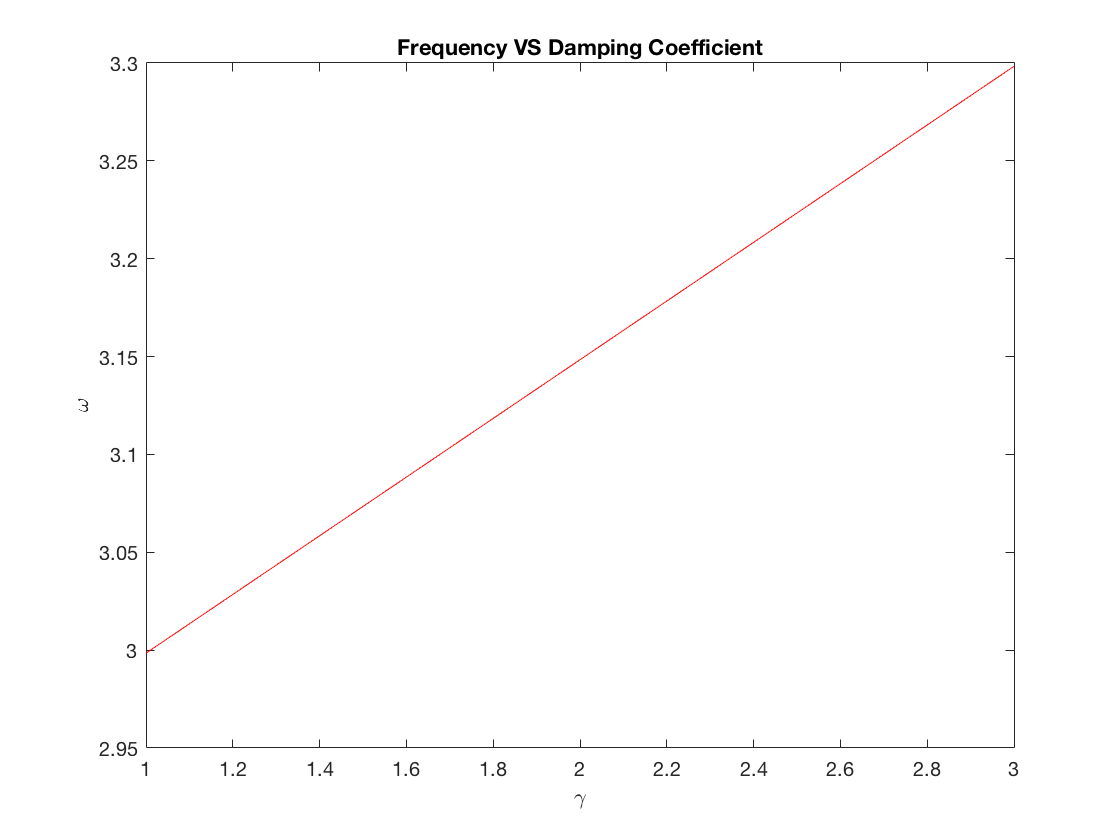

%additional runs for gamma = 1,2,3 

Gamma = [ 1, 2, 3];
T=zeros(1,length(Gamma));

for i=1:length(Gamma)
    T(i)=Damped_pendulummodified(1.09, 1, 0, 0, Gamma(i));
end  
w=6.28 ./ T(:); %T(:) reshapes all elements of T into a single column vector
%omega = 2pi/T
plot(Gamma, w, 'r');
title('Frequency VS Damping Coefficient')
xlabel('\gamma')
ylabel('\omega')

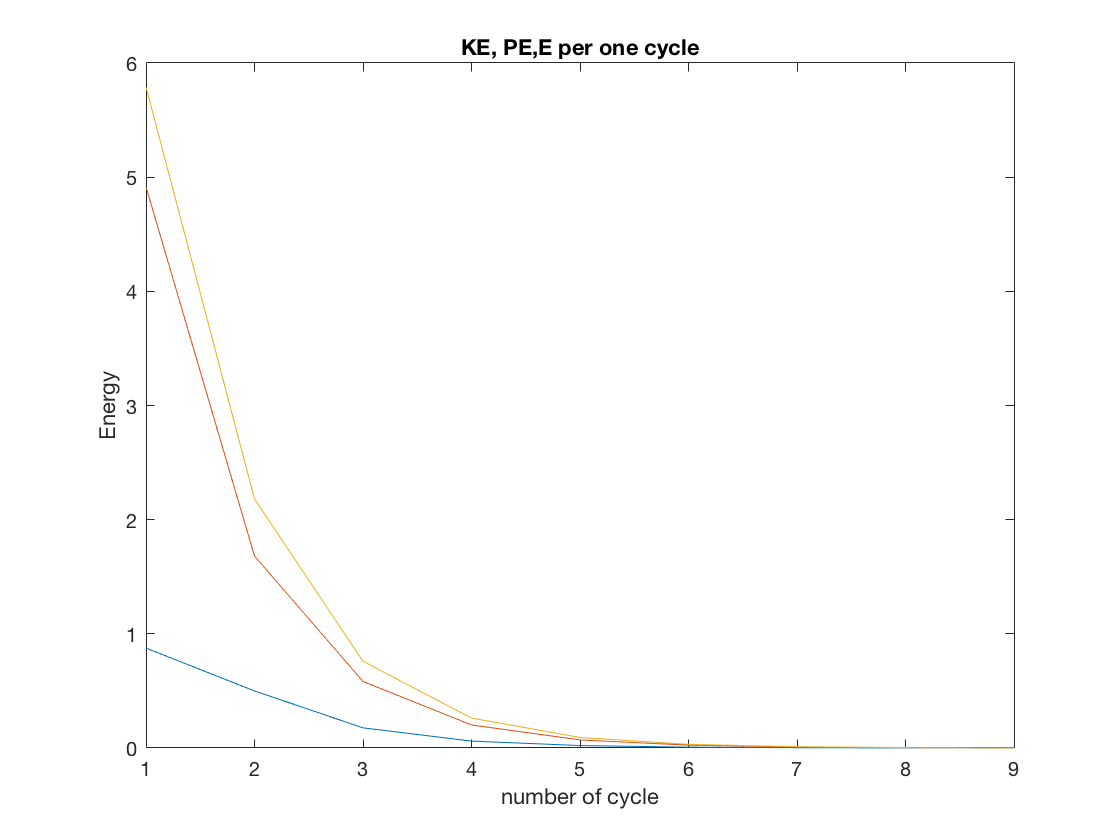


% c) compute avg of KE and PE and TotE over cycle

avgkenergy=[];
avgpenergy=[];
avgtotalE=[];
[T,sol]=Damped_pendulummodified(1.09, 1, 0, 0, 0.5);

ind= find(sol(:,3).*circshift(sol(:,3), [-1 0]) <= 0);
for i =1:(length(ind)-2) / 2 
    n=2 .* i -1;
    kenergy = 0.5 .* (1.09).^2 .* sol(ind(n): ind(n+2),3).^2;  % Kinetic Energy
    penergy =(9.81) .* (1.09) .* (1-cos(sol(ind(n): ind(n),2))) ; % Potential Energy
    totenergy=kenergy+penergy; 
    avgkenergy=[avgkenergy,mean(kenergy)];
    avgpenergy=[avgpenergy,mean(penergy)];
    avgtotalE=[avgtotalE,mean(totenergy)];
    
end    

n=1:(length(ind)-2) / 2 ;
plot(n,avgkenergy,n,avgpenergy,n,avgtotalE);
title('KE, PE,E per one cycle')
xlabel('number of cycle')
ylabel('Energy')

% d) compute time-dependence of theta & thetadot for Gamma = 4,5,6,7,8
% equilibrium condition: theta <0.0001 
%for Gamma >= 5 
Gamma=[4,5,6,7,8];
t_equil=zeros(1,length(Gamma)) 

t_equil =      0     0     0     0     0


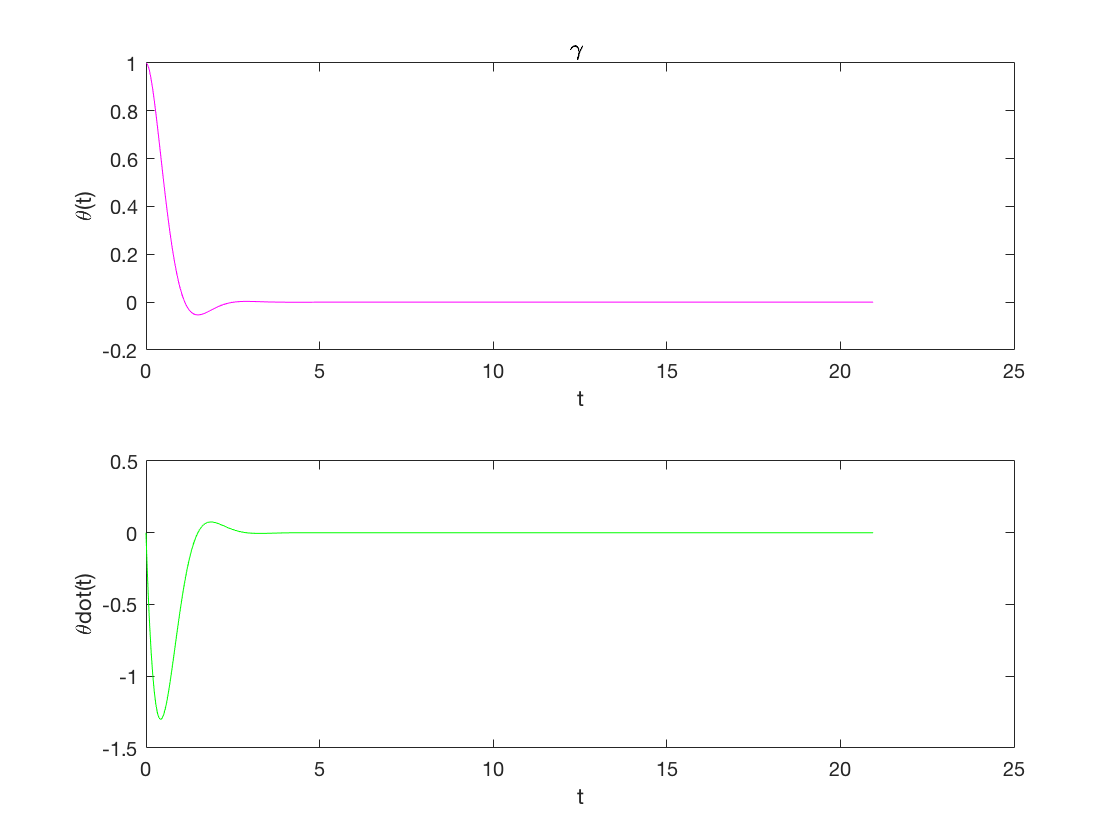

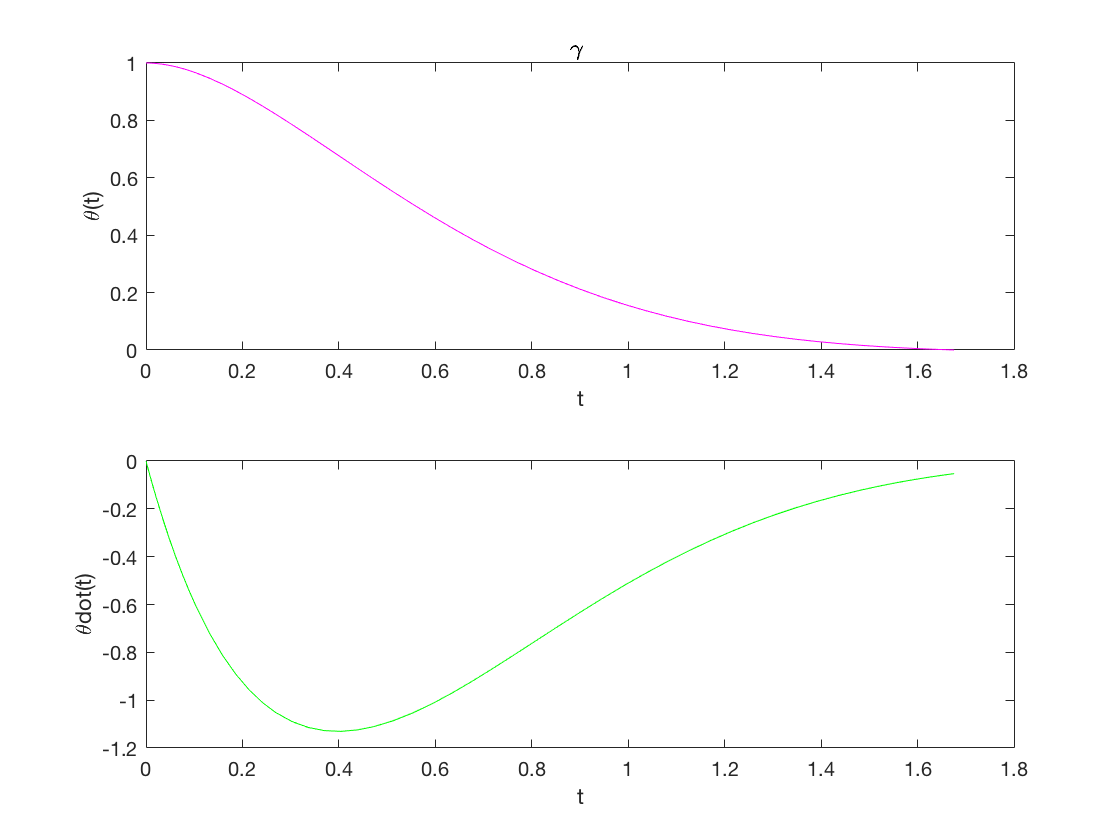

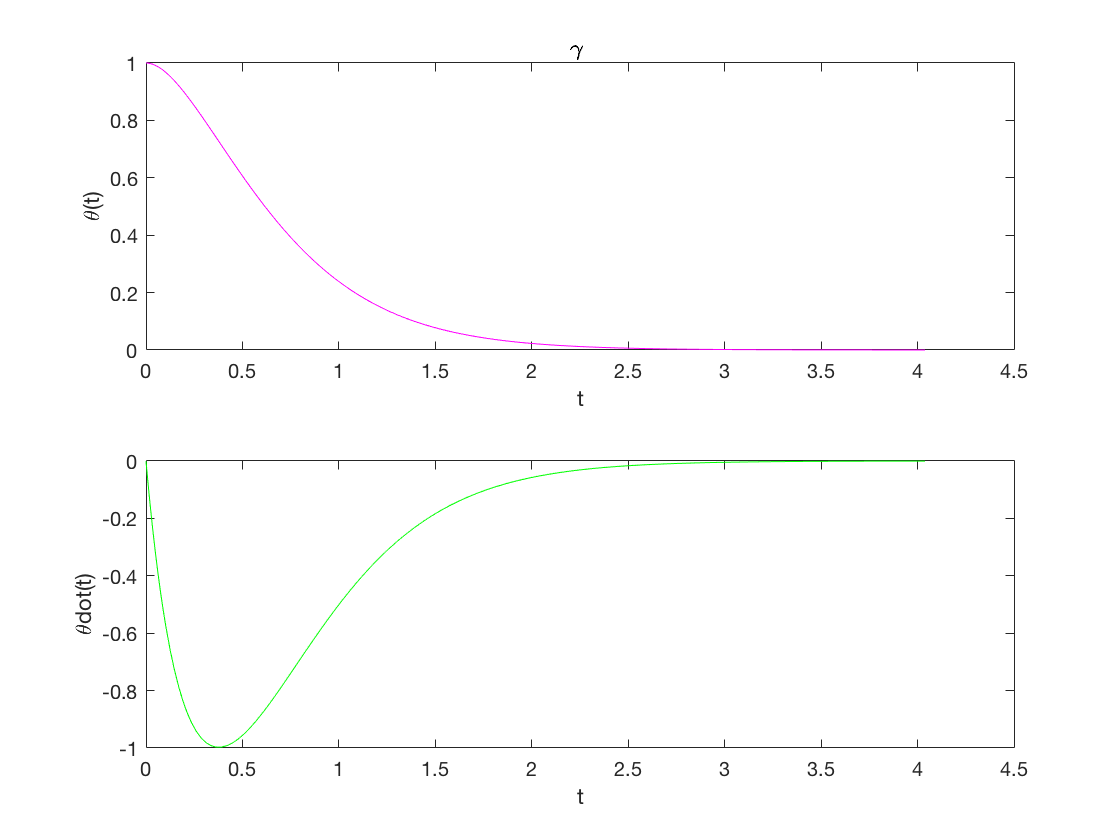

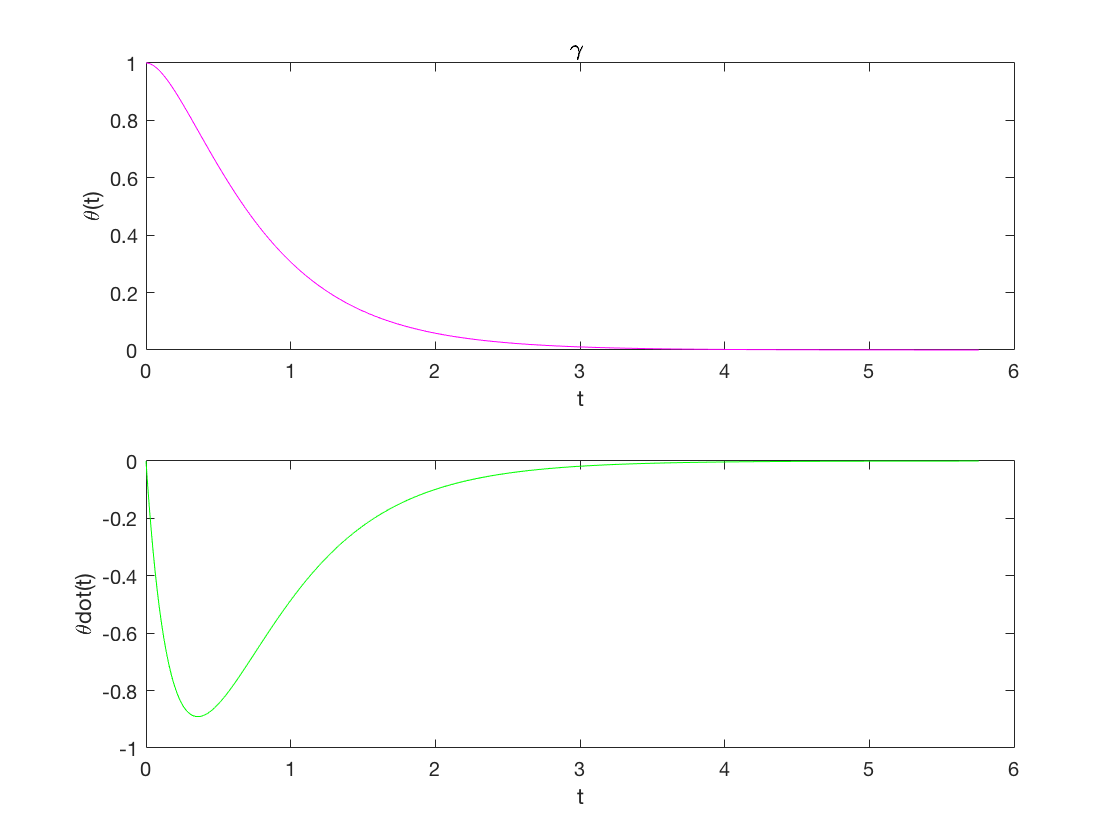


for i=1:length(Gamma)
    
   [T,sol] = Damped_pendulummodified(1.09, 1, 0, 0, Gamma(i));
   t_equil(i)=sol(end,1);
   figure;
    subplot(2,1,1);
    plot(sol(:,1),sol(:,2),'m');
    title(' \gamma  '); 
    xlabel('t')
    ylabel( '\theta(t)')
    
    subplot(2,1,2);
    plot(sol(:,1),sol(:,3), 'g');
    xlabel('t');
    ylabel('\thetadot(t)');
    
end    

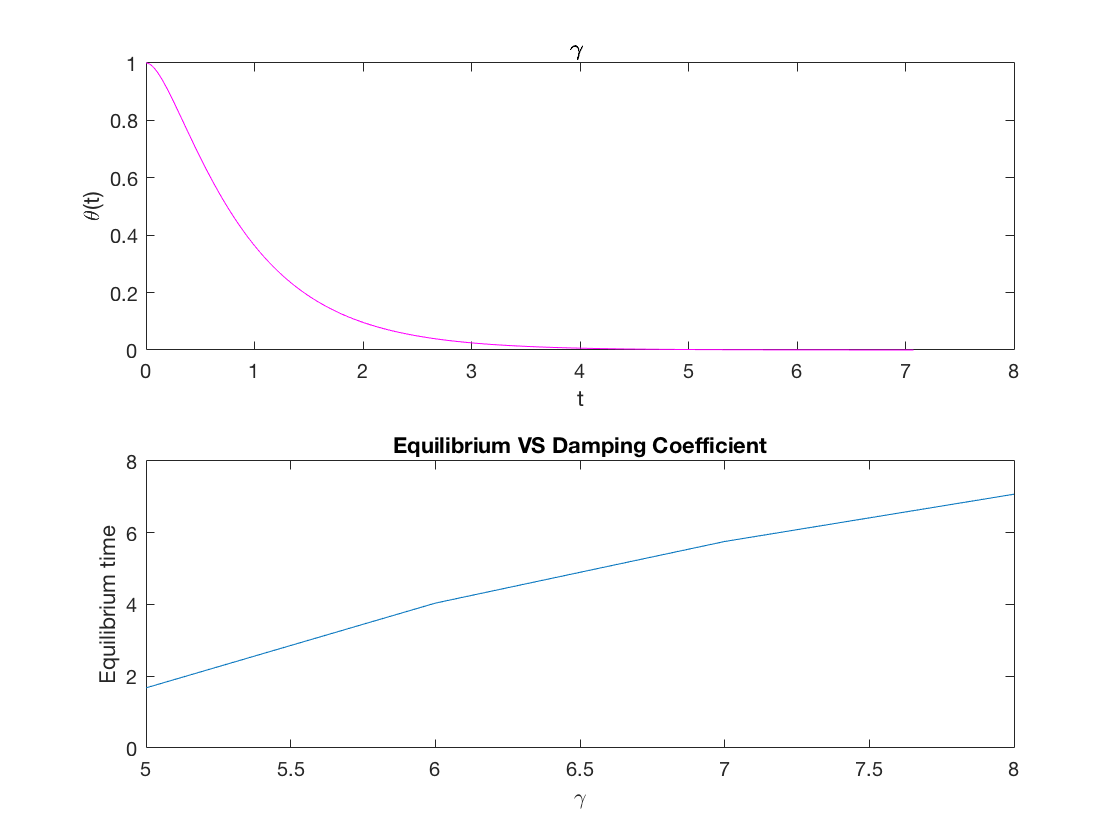


% Equilibrium:
plot(Gamma(2:end),t_equil(2:end));
title('Equilibrium VS Damping Coefficient');
xlabel('\gamma');
ylabel('Equilibrium time');

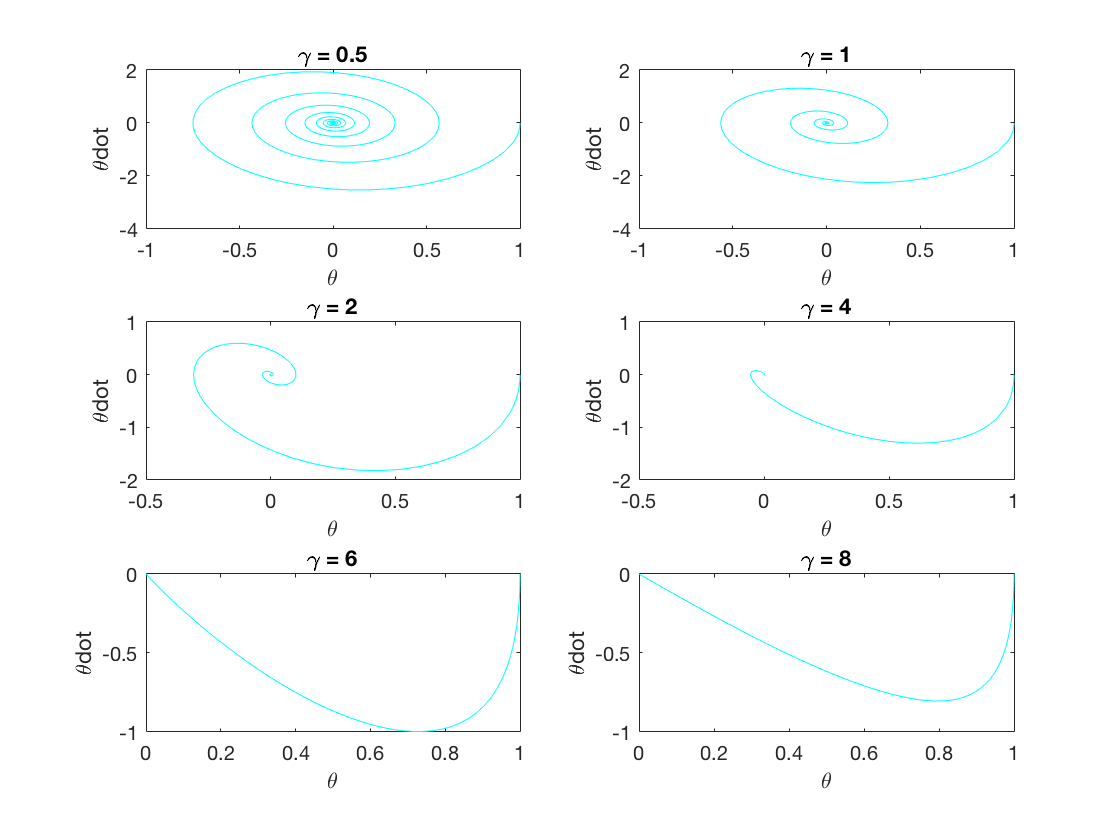

% e) Phase space diagram for omega0 =3, Gamma = 0.5,2,4,6,8 
 Gamma=[0.5,1,2,4,6,8];

for i=1:length(Gamma)
    
   [T,sol] = Damped_pendulummodified(1.09, 1, 0, 0, Gamma(i));
   
    
    subplot(3,2,i) %subplot(m,n,p) divides space m by n in position by p. 
    %the number m by n has to equal p so here i = 6 then m by n must be 3 by 2
    plot(sol(:,2),sol(:,3),'c');
    title(['\gamma = ' num2str(Gamma(i))])
    ylabel('\thetadot')
    xlabel('\theta')
    
end  